This livescript intend to visualize the raw BOLD signal laminar dependency, the tSNR laminar dependency, and also the Z-scored BOLD, with special focus on the trial type itself.

It works with the output of the BK_ROI_creation_GROUPLVLactivationconj.m script. The output file is saved for each subject separately (see exact path below) and called interimdata_rwls_'roiname'raw.mat. The raw, sampled BOLD timeseries data from along all the vertex pairs within the ROI. There are two images here, one is the raw BOLD signal laminar dependency in the whole ROI and only in the top 200 verte pairs (from which we make the inferences).

%check the bold response layerdependency
allsubj=[7349, 7356, 7361, 7375, 7376,...
         7383, 7402, 7403, 7404,...
         7405, 7408, 7414, 7415,...
         7425, 7426, 7433, 7434,...
         7435, 7443, 7444, 7445,...
         7448, 7449, 7452, 7453,...
         7454, 7455, 7456, 7457,...
         7468, 7469, 7482, 7484, 7485];




layermeans = zeros(20, length(allsubj));

myroiname='pIns';
hemisphere={'left' 'right'};
figurelocationpath='C:\Users\lenov\Documents\layerfMRI\E_stats\images\tomanuscipt\firstdrafts\supplementary\rawBOLDlaminardependency\';
for hemishperes=1:2
    figure('Position',[100, 100, 2400, 1200]);
    plotidx=0;
    for subj=allsubj
        rwdtmtrx=loadrawdatamatrix(subj,myroiname);
        
        % load('C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7402\functionalmasks\interimdata_rwls_DLPFCraw.mat')
        plotidx=plotidx+1;
        subplot(5,7,plotidx);
        tmpdata=rwdtmtrx.interimdata_columns{1,2}{hemishperes,1};
        vertexmean=squeeze(mean(tmpdata,1));
        layermean=mean(vertexmean,2)';
        plot(1:20, layermean, '-r', 'LineWidth', 1);
        hold on
        errorbar(1:20, layermean, std(vertexmean, [], 2), 'k');
        
    
        title([ 'Subject ' num2str(subj)]);  % add a title to each subplot
        hold off
        layermeans(:, plotidx) = layermean;
    end
    
    saveas(gcf, [figurelocationpath myroiname hemisphere{hemishperes} 'layer_mean_std_eachsubj.jpg'], 'jpeg');
    
    
    figure;  % create a new figure to visualize the layermean matrix
    plot(1:20, mean(layermeans, 2), '-r', 'LineWidth', 1);
    hold on
    errorbar(1:20, mean(layermeans, 2), std(layermeans, [], 2), 'k');
    hold off
    xlabel('laminar depth (WM to CSF)');
    ylabel(' raw BOLD signal');
    title('Grand average across subjects');
    saveas(gcf, [figurelocationpath myroiname hemisphere{hemishperes} 'layer_mean_std_subjavg.jpg'], 'jpeg');
end

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7349\functionalmasks\interimdata_rwls_pInsraw.mat


Raw BOLD and also tSNR BOLD for all or only a selected number of vertices (200 is hard coded).

plotidx=0;
subplotsize=[8 4];
allsubjlayer={};
topcolumnnumber=200; %used this previously
layermeans = zeros(20, length(allsubj));

myroiname='S1';
hemisphere={'left' 'right'};
figuretype='tSNR'; %possible input: 'raw', 'tSNR', 
figurelocationpath=['C:\Users\lenov\Documents\layerfMRI\E_stats\images\tomanuscipt\firstdrafts\supplementary\' figuretype 'BOLDlaminardependency\';]

figurelocationpath = 'C:\Users\lenov\Documents\layerfMRI\E_stats\images\tomanuscipt\firstdrafts\supplementary\tSNRBOLDlaminardependency\'

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7349\functionalmasks\interimdata_rwls_S1raw.mat
The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7356\functionalmasks\interimdata_rwls_S1raw.mat
The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7361\functionalmasks\interimdata_rwls_S1raw.mat
The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7375\functionalmasks\interimdata_rwls_S1raw.mat
The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7376\functionalmasks\interimdata_rwls_S1raw.mat
The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7383\functionalmasks\interimdata_rwls_S1raw.mat
The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7402\functionalmasks\interimdata_rwls_S1raw.mat
The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7403\functionalm

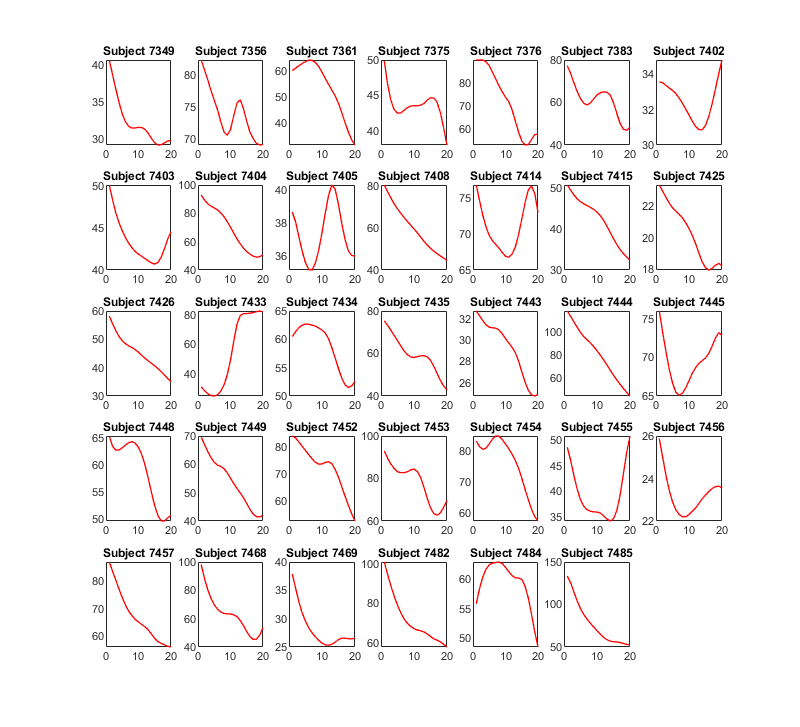

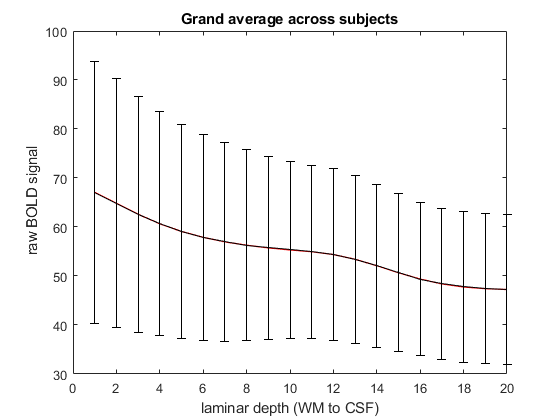

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7349\functionalmasks\interimdata_rwls_S1raw.mat
The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7356\functionalmasks\interimdata_rwls_S1raw.mat
The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7361\functionalmasks\interimdata_rwls_S1raw.mat
The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7375\functionalmasks\interimdata_rwls_S1raw.mat
The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7376\functionalmasks\interimdata_rwls_S1raw.mat
The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7383\functionalmasks\interimdata_rwls_S1raw.mat
The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7402\functionalmasks\interimdata_rwls_S1raw.mat
The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7403\functionalm

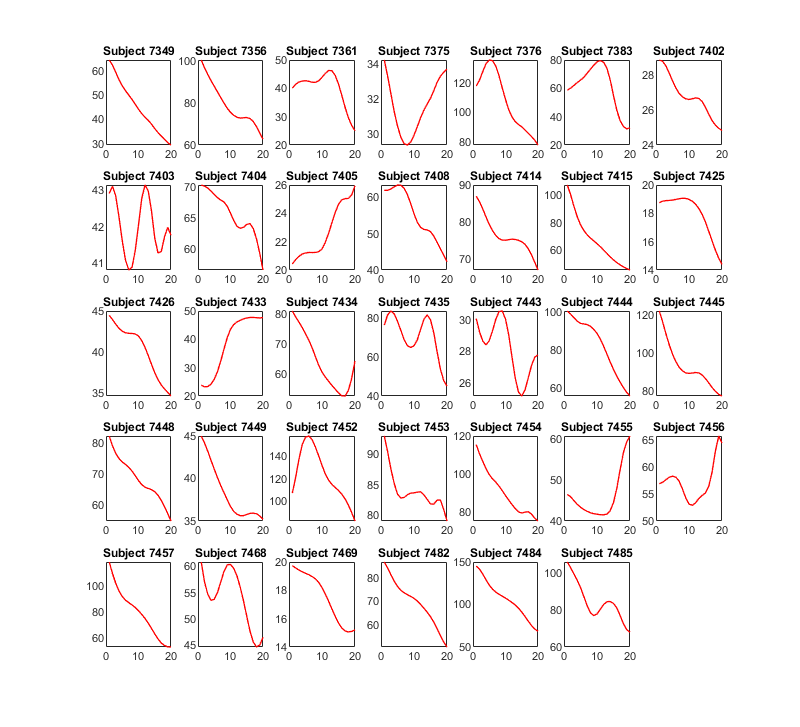

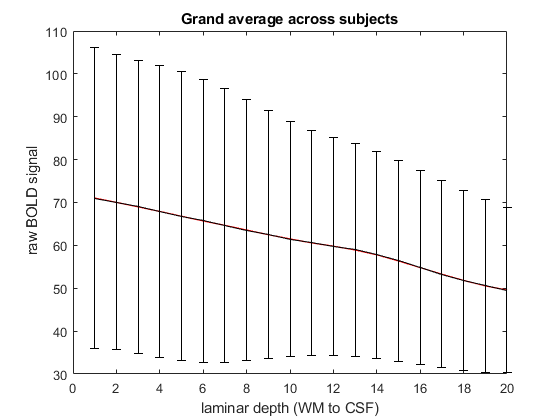

clustersize=0;
for hemishperes=1:2
    figure('Position',[100, 100, 2400, 1200]);
    plotidx=0;
    for subj=allsubj
    %     roipath='C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\';
        rwdtmtrx=loadrawdatamatrix(subj,myroiname);
    %     columnartsfile=[roipath num2str(subj{:}) '\functionalmasks\interimdata_rwls_' myroiname 'raw.mat'];
    %     if exist(columnartsfile,"file")
    %         disp([num2str(subj{:}) ' subject columnar info r'])
    %         plotidx=plotidx+1;
    plotidx=plotidx+1;
    subplot(5,7,plotidx);
    if clustersize==200
            [columnwisestat,~,~]=BK_layer_sampling_pain_study_pipeline(num2cell(subj),'glmestimate',myroiname,'raw','no','maineff');
    %         allsubjid(plotidx)=subj{:};
    %         allsubjlayer{plotidx}=layerwisestat;
    %         allsubjcoldistr{plotidx}=columndistribution;
    %         allsubjstat{plotidx}=stat;
            [top200Values, top200Indices] =maxk(columnwisestat(hemishperes).T(:,3),topcolumnnumber);
            
            % Filter the indices where the values are positive
            positiveIndices = top200Indices(top200Values > 0);
            % Check if any negative values were removed
            if length(positiveIndices) < topcolumnnumber
                warning('The top 200 values contained negative numbers. Only %d positive values are retained.', length(positiveIndices));
            end
            
            tmpdata=rwdtmtrx.interimdata_columns{1,2}{hemishperes,1};
            tmpdata=tmpdata(positiveIndices,:,:);
    elseif clustersize==0
        tmpdata=rwdtmtrx.interimdata_columns{1,2}{hemishperes,1};
    end
     
            vertexmean=squeeze(mean(tmpdata,1));
            noise_std = std(vertexmean, 0, 2);
            layermean=mean(vertexmean,2);
            tSNR=layermean./noise_std;
            if strcmp(figuretype,'raw')
                imagedata=layermean;
                plot(1:20, imagedata', '-r', 'LineWidth', 1);                
                hold on
                errorbar(1:20, imagedata', noise_std, 'k');
            elseif strcmp(figuretype,'tSNR')
                imagedata=tSNR;
                plot(1:20, imagedata', '-r', 'LineWidth', 1);
            end
            
            
        
            title([ 'Subject ' num2str(subj)]);  % add a title to each subplot
            hold off
            layermeans(:, plotidx) = imagedata';
    %     else
    %         disp([num2str(subj{:}) ' subject has  no sampled cluster'])
    %     end
    
    end
    saveas(gcf, [figurelocationpath myroiname hemisphere{hemishperes} figuretype 'layer' num2str(clustersize) 'vertices_mean_std_eachsubj.jpg'], 'jpeg');
    
    
    figure;  % create a new figure to visualize the layermean matrix
    plot(1:20, mean(layermeans, 2), '-r', 'LineWidth', 1);
    hold on
    errorbar(1:20, mean(layermeans, 2), std(layermeans, [], 2), 'k');
    hold off
    xlabel('laminar depth (WM to CSF)');
    ylabel(' raw BOLD signal');
    title('Grand average across subjects');
    saveas(gcf, [figurelocationpath myroiname hemisphere{hemishperes} figuretype 'layer' num2str(clustersize) 'vertices_mean_std_subjavg.jpg'], 'jpeg');
end

Trialwise timeseires (TS) from the raw BOLD data in all the voxels and in a subset of voxels(200 harcoded).

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7349\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7349The number of columns within the funcitonal mask: 769
Subject:7349The number of columns acitvating in each run(t>0) for cognition: 206
Subject:7349The number of columns acitvating in each run(t>0) for pain: 496
Subject:7349The number of columns acitvating in each run(t>0) for cognition AND pain: 143
-------------------------------------------------------------
Subject:7349The number of columns within the funcitonal mask: 769
Subject:7349The number of columns acitvating in each run(t>1) for cognition: 50
Subject:7349The number of columns acitvating in each run(t>1) for pain: 206
Subject:7349The number of columns acitvating in each run(t>1) for cognition AND pain: 19
-------------------------------------------------------------
Subject:7349The number of columns within the funcitonal mask: 1865
Subject:7349The number of columns acitvating in each run(t>0) for cognition: 658
Subject:7349The number of columns acitvating in each run(t>0) for pain: 1265
Subject:7349The number of c

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7356\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7356The number of columns within the funcitonal mask: 691
Subject:7356The number of columns acitvating in each run(t>0) for cognition: 421
Subject:7356The number of columns acitvating in each run(t>0) for pain: 314
Subject:7356The number of columns acitvating in each run(t>0) for cognition AND pain: 188
-------------------------------------------------------------
Subject:7356The number of columns within the funcitonal mask: 691
Subject:7356The number of columns acitvating in each run(t>1) for cognition: 171
Subject:7356The number of columns acitvating in each run(t>1) for pain: 108
Subject:7356The number of columns acitvating in each run(t>1) for cognition AND pain: 24
-------------------------------------------------------------
Subject:7356The number of columns within the funcitonal mask: 1383
Subject:7356The number of columns acitvating in each run(t>0) for cognition: 807
Subject:7356The number of columns acitvating in each run(t>0) for pain: 649
Subject:7356The number of c

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7361\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7361The number of columns within the funcitonal mask: 749
Subject:7361The number of columns acitvating in each run(t>0) for cognition: 378
Subject:7361The number of columns acitvating in each run(t>0) for pain: 550
Subject:7361The number of columns acitvating in each run(t>0) for cognition AND pain: 287
-------------------------------------------------------------
Subject:7361The number of columns within the funcitonal mask: 749
Subject:7361The number of columns acitvating in each run(t>1) for cognition: 128
Subject:7361The number of columns acitvating in each run(t>1) for pain: 293
Subject:7361The number of columns acitvating in each run(t>1) for cognition AND pain: 60
-------------------------------------------------------------
Subject:7361The number of columns within the funcitonal mask: 1748
Subject:7361The number of columns acitvating in each run(t>0) for cognition: 824
Subject:7361The number of columns acitvating in each run(t>0) for pain: 1413
Subject:7361The number of 

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7375\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7375The number of columns within the funcitonal mask: 699
Subject:7375The number of columns acitvating in each run(t>0) for cognition: 354
Subject:7375The number of columns acitvating in each run(t>0) for pain: 288
Subject:7375The number of columns acitvating in each run(t>0) for cognition AND pain: 171
-------------------------------------------------------------
Subject:7375The number of columns within the funcitonal mask: 699
Subject:7375The number of columns acitvating in each run(t>1) for cognition: 124
Subject:7375The number of columns acitvating in each run(t>1) for pain: 109
Subject:7375The number of columns acitvating in each run(t>1) for cognition AND pain: 26
-------------------------------------------------------------
Subject:7375The number of columns within the funcitonal mask: 1876
Subject:7375The number of columns acitvating in each run(t>0) for cognition: 841
Subject:7375The number of columns acitvating in each run(t>0) for pain: 1080
Subject:7375The number of 

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7376\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7376The number of columns within the funcitonal mask: 803
Subject:7376The number of columns acitvating in each run(t>0) for cognition: 458
Subject:7376The number of columns acitvating in each run(t>0) for pain: 510
Subject:7376The number of columns acitvating in each run(t>0) for cognition AND pain: 286
-------------------------------------------------------------
Subject:7376The number of columns within the funcitonal mask: 803
Subject:7376The number of columns acitvating in each run(t>1) for cognition: 162
Subject:7376The number of columns acitvating in each run(t>1) for pain: 219
Subject:7376The number of columns acitvating in each run(t>1) for cognition AND pain: 40
-------------------------------------------------------------
Subject:7376The number of columns within the funcitonal mask: 1683
Subject:7376The number of columns acitvating in each run(t>0) for cognition: 774
Subject:7376The number of columns acitvating in each run(t>0) for pain: 1159
Subject:7376The number of 

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7383\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7383The number of columns within the funcitonal mask: 864
Subject:7383The number of columns acitvating in each run(t>0) for cognition: 575
Subject:7383The number of columns acitvating in each run(t>0) for pain: 391
Subject:7383The number of columns acitvating in each run(t>0) for cognition AND pain: 239
-------------------------------------------------------------
Subject:7383The number of columns within the funcitonal mask: 864
Subject:7383The number of columns acitvating in each run(t>1) for cognition: 288
Subject:7383The number of columns acitvating in each run(t>1) for pain: 133
Subject:7383The number of columns acitvating in each run(t>1) for cognition AND pain: 31
-------------------------------------------------------------
Subject:7383The number of columns within the funcitonal mask: 1655
Subject:7383The number of columns acitvating in each run(t>0) for cognition: 999
Subject:7383The number of columns acitvating in each run(t>0) for pain: 677
Subject:7383The number of c

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7402\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7402The number of columns within the funcitonal mask: 1475
Subject:7402The number of columns acitvating in each run(t>0) for cognition: 1038
Subject:7402The number of columns acitvating in each run(t>0) for pain: 533
Subject:7402The number of columns acitvating in each run(t>0) for cognition AND pain: 369
-------------------------------------------------------------
Subject:7402The number of columns within the funcitonal mask: 1475
Subject:7402The number of columns acitvating in each run(t>1) for cognition: 503
Subject:7402The number of columns acitvating in each run(t>1) for pain: 130
Subject:7402The number of columns acitvating in each run(t>1) for cognition AND pain: 24
-------------------------------------------------------------
Subject:7402The number of columns within the funcitonal mask: 3258
Subject:7402The number of columns acitvating in each run(t>0) for cognition: 2582
Subject:7402The number of columns acitvating in each run(t>0) for pain: 1095
Subject:7402The number

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7403\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7403The number of columns within the funcitonal mask: 792
Subject:7403The number of columns acitvating in each run(t>0) for cognition: 455
Subject:7403The number of columns acitvating in each run(t>0) for pain: 312
Subject:7403The number of columns acitvating in each run(t>0) for cognition AND pain: 181
-------------------------------------------------------------
Subject:7403The number of columns within the funcitonal mask: 792
Subject:7403The number of columns acitvating in each run(t>1) for cognition: 161
Subject:7403The number of columns acitvating in each run(t>1) for pain: 68
Subject:7403The number of columns acitvating in each run(t>1) for cognition AND pain: 17
-------------------------------------------------------------
Subject:7403The number of columns within the funcitonal mask: 1905
Subject:7403The number of columns acitvating in each run(t>0) for cognition: 1028
Subject:7403The number of columns acitvating in each run(t>0) for pain: 816
Subject:7403The number of c

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7404\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7404The number of columns within the funcitonal mask: 749
Subject:7404The number of columns acitvating in each run(t>0) for cognition: 446
Subject:7404The number of columns acitvating in each run(t>0) for pain: 378
Subject:7404The number of columns acitvating in each run(t>0) for cognition AND pain: 221
-------------------------------------------------------------
Subject:7404The number of columns within the funcitonal mask: 749
Subject:7404The number of columns acitvating in each run(t>1) for cognition: 192
Subject:7404The number of columns acitvating in each run(t>1) for pain: 148
Subject:7404The number of columns acitvating in each run(t>1) for cognition AND pain: 34
-------------------------------------------------------------
Subject:7404The number of columns within the funcitonal mask: 1443
Subject:7404The number of columns acitvating in each run(t>0) for cognition: 883
Subject:7404The number of columns acitvating in each run(t>0) for pain: 857
Subject:7404The number of c

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7405\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7405The number of columns within the funcitonal mask: 738
Subject:7405The number of columns acitvating in each run(t>0) for cognition: 591
Subject:7405The number of columns acitvating in each run(t>0) for pain: 442
Subject:7405The number of columns acitvating in each run(t>0) for cognition AND pain: 353
-------------------------------------------------------------
Subject:7405The number of columns within the funcitonal mask: 738
Subject:7405The number of columns acitvating in each run(t>1) for cognition: 375
Subject:7405The number of columns acitvating in each run(t>1) for pain: 159
Subject:7405The number of columns acitvating in each run(t>1) for cognition AND pain: 80
-------------------------------------------------------------
Subject:7405The number of columns within the funcitonal mask: 1352
Subject:7405The number of columns acitvating in each run(t>0) for cognition: 1117
Subject:7405The number of columns acitvating in each run(t>0) for pain: 846
Subject:7405The number of 

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7408\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7408The number of columns within the funcitonal mask: 867
Subject:7408The number of columns acitvating in each run(t>0) for cognition: 537
Subject:7408The number of columns acitvating in each run(t>0) for pain: 370
Subject:7408The number of columns acitvating in each run(t>0) for cognition AND pain: 214
-------------------------------------------------------------
Subject:7408The number of columns within the funcitonal mask: 867
Subject:7408The number of columns acitvating in each run(t>1) for cognition: 218
Subject:7408The number of columns acitvating in each run(t>1) for pain: 117
Subject:7408The number of columns acitvating in each run(t>1) for cognition AND pain: 28
-------------------------------------------------------------
Subject:7408The number of columns within the funcitonal mask: 2238
Subject:7408The number of columns acitvating in each run(t>0) for cognition: 1610
Subject:7408The number of columns acitvating in each run(t>0) for pain: 869
Subject:7408The number of 

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7414\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7414The number of columns within the funcitonal mask: 738
Subject:7414The number of columns acitvating in each run(t>0) for cognition: 433
Subject:7414The number of columns acitvating in each run(t>0) for pain: 412
Subject:7414The number of columns acitvating in each run(t>0) for cognition AND pain: 237
-------------------------------------------------------------
Subject:7414The number of columns within the funcitonal mask: 738
Subject:7414The number of columns acitvating in each run(t>1) for cognition: 175
Subject:7414The number of columns acitvating in each run(t>1) for pain: 144
Subject:7414The number of columns acitvating in each run(t>1) for cognition AND pain: 35
-------------------------------------------------------------
Subject:7414The number of columns within the funcitonal mask: 1669
Subject:7414The number of columns acitvating in each run(t>0) for cognition: 977
Subject:7414The number of columns acitvating in each run(t>0) for pain: 862
Subject:7414The number of c

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7415\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7415The number of columns within the funcitonal mask: 777
Subject:7415The number of columns acitvating in each run(t>0) for cognition: 339
Subject:7415The number of columns acitvating in each run(t>0) for pain: 257
Subject:7415The number of columns acitvating in each run(t>0) for cognition AND pain: 124
-------------------------------------------------------------
Subject:7415The number of columns within the funcitonal mask: 777
Subject:7415The number of columns acitvating in each run(t>1) for cognition: 114
Subject:7415The number of columns acitvating in each run(t>1) for pain: 59
Subject:7415The number of columns acitvating in each run(t>1) for cognition AND pain: 7
-------------------------------------------------------------
Subject:7415The number of columns within the funcitonal mask: 1925
Subject:7415The number of columns acitvating in each run(t>0) for cognition: 806
Subject:7415The number of columns acitvating in each run(t>0) for pain: 726
Subject:7415The number of col

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7425\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7425The number of columns within the funcitonal mask: 615
Subject:7425The number of columns acitvating in each run(t>0) for cognition: 309
Subject:7425The number of columns acitvating in each run(t>0) for pain: 337
Subject:7425The number of columns acitvating in each run(t>0) for cognition AND pain: 195
-------------------------------------------------------------
Subject:7425The number of columns within the funcitonal mask: 615
Subject:7425The number of columns acitvating in each run(t>1) for cognition: 146
Subject:7425The number of columns acitvating in each run(t>1) for pain: 129
Subject:7425The number of columns acitvating in each run(t>1) for cognition AND pain: 49
-------------------------------------------------------------
Subject:7425The number of columns within the funcitonal mask: 1546
Subject:7425The number of columns acitvating in each run(t>0) for cognition: 714
Subject:7425The number of columns acitvating in each run(t>0) for pain: 779
Subject:7425The number of c

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7426\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7426The number of columns within the funcitonal mask: 896
Subject:7426The number of columns acitvating in each run(t>0) for cognition: 622
Subject:7426The number of columns acitvating in each run(t>0) for pain: 430
Subject:7426The number of columns acitvating in each run(t>0) for cognition AND pain: 296
-------------------------------------------------------------
Subject:7426The number of columns within the funcitonal mask: 896
Subject:7426The number of columns acitvating in each run(t>1) for cognition: 317
Subject:7426The number of columns acitvating in each run(t>1) for pain: 137
Subject:7426The number of columns acitvating in each run(t>1) for cognition AND pain: 46
-------------------------------------------------------------
Subject:7426The number of columns within the funcitonal mask: 1694
Subject:7426The number of columns acitvating in each run(t>0) for cognition: 1008
Subject:7426The number of columns acitvating in each run(t>0) for pain: 765
Subject:7426The number of 

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7433\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7433The number of columns within the funcitonal mask: 835
Subject:7433The number of columns acitvating in each run(t>0) for cognition: 385
Subject:7433The number of columns acitvating in each run(t>0) for pain: 423
Subject:7433The number of columns acitvating in each run(t>0) for cognition AND pain: 188
-------------------------------------------------------------
Subject:7433The number of columns within the funcitonal mask: 835
Subject:7433The number of columns acitvating in each run(t>1) for cognition: 127
Subject:7433The number of columns acitvating in each run(t>1) for pain: 146
Subject:7433The number of columns acitvating in each run(t>1) for cognition AND pain: 23
-------------------------------------------------------------
Subject:7433The number of columns within the funcitonal mask: 1461
Subject:7433The number of columns acitvating in each run(t>0) for cognition: 671
Subject:7433The number of columns acitvating in each run(t>0) for pain: 711
Subject:7433The number of c

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7434\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7434The number of columns within the funcitonal mask: 726
Subject:7434The number of columns acitvating in each run(t>0) for cognition: 548
Subject:7434The number of columns acitvating in each run(t>0) for pain: 432
Subject:7434The number of columns acitvating in each run(t>0) for cognition AND pain: 338
-------------------------------------------------------------
Subject:7434The number of columns within the funcitonal mask: 726
Subject:7434The number of columns acitvating in each run(t>1) for cognition: 258
Subject:7434The number of columns acitvating in each run(t>1) for pain: 162
Subject:7434The number of columns acitvating in each run(t>1) for cognition AND pain: 57
-------------------------------------------------------------
Subject:7434The number of columns within the funcitonal mask: 1488
Subject:7434The number of columns acitvating in each run(t>0) for cognition: 904
Subject:7434The number of columns acitvating in each run(t>0) for pain: 969
Subject:7434The number of c

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7435\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7435The number of columns within the funcitonal mask: 737
Subject:7435The number of columns acitvating in each run(t>0) for cognition: 495
Subject:7435The number of columns acitvating in each run(t>0) for pain: 308
Subject:7435The number of columns acitvating in each run(t>0) for cognition AND pain: 202
-------------------------------------------------------------
Subject:7435The number of columns within the funcitonal mask: 737
Subject:7435The number of columns acitvating in each run(t>1) for cognition: 249
Subject:7435The number of columns acitvating in each run(t>1) for pain: 73
Subject:7435The number of columns acitvating in each run(t>1) for cognition AND pain: 27
-------------------------------------------------------------
Subject:7435The number of columns within the funcitonal mask: 1336
Subject:7435The number of columns acitvating in each run(t>0) for cognition: 1027
Subject:7435The number of columns acitvating in each run(t>0) for pain: 552
Subject:7435The number of c

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7443\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7443The number of columns within the funcitonal mask: 897
Subject:7443The number of columns acitvating in each run(t>0) for cognition: 552
Subject:7443The number of columns acitvating in each run(t>0) for pain: 515
Subject:7443The number of columns acitvating in each run(t>0) for cognition AND pain: 316
-------------------------------------------------------------
Subject:7443The number of columns within the funcitonal mask: 897
Subject:7443The number of columns acitvating in each run(t>1) for cognition: 236
Subject:7443The number of columns acitvating in each run(t>1) for pain: 205
Subject:7443The number of columns acitvating in each run(t>1) for cognition AND pain: 53
-------------------------------------------------------------
Subject:7443The number of columns within the funcitonal mask: 1369
Subject:7443The number of columns acitvating in each run(t>0) for cognition: 695
Subject:7443The number of columns acitvating in each run(t>0) for pain: 766
Subject:7443The number of c

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7444\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7444The number of columns within the funcitonal mask: 976
Subject:7444The number of columns acitvating in each run(t>0) for cognition: 683
Subject:7444The number of columns acitvating in each run(t>0) for pain: 573
Subject:7444The number of columns acitvating in each run(t>0) for cognition AND pain: 397
-------------------------------------------------------------
Subject:7444The number of columns within the funcitonal mask: 976
Subject:7444The number of columns acitvating in each run(t>1) for cognition: 354
Subject:7444The number of columns acitvating in each run(t>1) for pain: 193
Subject:7444The number of columns acitvating in each run(t>1) for cognition AND pain: 69
-------------------------------------------------------------
Subject:7444The number of columns within the funcitonal mask: 2159
Subject:7444The number of columns acitvating in each run(t>0) for cognition: 1648
Subject:7444The number of columns acitvating in each run(t>0) for pain: 1308
Subject:7444The number of

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7445\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7445The number of columns within the funcitonal mask: 692
Subject:7445The number of columns acitvating in each run(t>0) for cognition: 365
Subject:7445The number of columns acitvating in each run(t>0) for pain: 331
Subject:7445The number of columns acitvating in each run(t>0) for cognition AND pain: 159
-------------------------------------------------------------
Subject:7445The number of columns within the funcitonal mask: 692
Subject:7445The number of columns acitvating in each run(t>1) for cognition: 152
Subject:7445The number of columns acitvating in each run(t>1) for pain: 109
Subject:7445The number of columns acitvating in each run(t>1) for cognition AND pain: 13
-------------------------------------------------------------
Subject:7445The number of columns within the funcitonal mask: 1635
Subject:7445The number of columns acitvating in each run(t>0) for cognition: 826
Subject:7445The number of columns acitvating in each run(t>0) for pain: 852
Subject:7445The number of c

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7448\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7448The number of columns within the funcitonal mask: 980
Subject:7448The number of columns acitvating in each run(t>0) for cognition: 733
Subject:7448The number of columns acitvating in each run(t>0) for pain: 595
Subject:7448The number of columns acitvating in each run(t>0) for cognition AND pain: 466
-------------------------------------------------------------
Subject:7448The number of columns within the funcitonal mask: 980
Subject:7448The number of columns acitvating in each run(t>1) for cognition: 371
Subject:7448The number of columns acitvating in each run(t>1) for pain: 260
Subject:7448The number of columns acitvating in each run(t>1) for cognition AND pain: 113
-------------------------------------------------------------
Subject:7448The number of columns within the funcitonal mask: 1698
Subject:7448The number of columns acitvating in each run(t>0) for cognition: 1259
Subject:7448The number of columns acitvating in each run(t>0) for pain: 993
Subject:7448The number of

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7449\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7449The number of columns within the funcitonal mask: 963
Subject:7449The number of columns acitvating in each run(t>0) for cognition: 508
Subject:7449The number of columns acitvating in each run(t>0) for pain: 369
Subject:7449The number of columns acitvating in each run(t>0) for cognition AND pain: 206
-------------------------------------------------------------
Subject:7449The number of columns within the funcitonal mask: 963
Subject:7449The number of columns acitvating in each run(t>1) for cognition: 191
Subject:7449The number of columns acitvating in each run(t>1) for pain: 101
Subject:7449The number of columns acitvating in each run(t>1) for cognition AND pain: 22
-------------------------------------------------------------
Subject:7449The number of columns within the funcitonal mask: 1652
Subject:7449The number of columns acitvating in each run(t>0) for cognition: 818
Subject:7449The number of columns acitvating in each run(t>0) for pain: 566
Subject:7449The number of c

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7452\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7452The number of columns within the funcitonal mask: 866
Subject:7452The number of columns acitvating in each run(t>0) for cognition: 502
Subject:7452The number of columns acitvating in each run(t>0) for pain: 398
Subject:7452The number of columns acitvating in each run(t>0) for cognition AND pain: 225
-------------------------------------------------------------
Subject:7452The number of columns within the funcitonal mask: 866
Subject:7452The number of columns acitvating in each run(t>1) for cognition: 196
Subject:7452The number of columns acitvating in each run(t>1) for pain: 114
Subject:7452The number of columns acitvating in each run(t>1) for cognition AND pain: 19
-------------------------------------------------------------
Subject:7452The number of columns within the funcitonal mask: 1462
Subject:7452The number of columns acitvating in each run(t>0) for cognition: 775
Subject:7452The number of columns acitvating in each run(t>0) for pain: 638
Subject:7452The number of c

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7453\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7453The number of columns within the funcitonal mask: 870
Subject:7453The number of columns acitvating in each run(t>0) for cognition: 416
Subject:7453The number of columns acitvating in each run(t>0) for pain: 465
Subject:7453The number of columns acitvating in each run(t>0) for cognition AND pain: 245
-------------------------------------------------------------
Subject:7453The number of columns within the funcitonal mask: 870
Subject:7453The number of columns acitvating in each run(t>1) for cognition: 148
Subject:7453The number of columns acitvating in each run(t>1) for pain: 141
Subject:7453The number of columns acitvating in each run(t>1) for cognition AND pain: 30
-------------------------------------------------------------
Subject:7453The number of columns within the funcitonal mask: 1679
Subject:7453The number of columns acitvating in each run(t>0) for cognition: 793
Subject:7453The number of columns acitvating in each run(t>0) for pain: 845
Subject:7453The number of c

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7454\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7454The number of columns within the funcitonal mask: 832
Subject:7454The number of columns acitvating in each run(t>0) for cognition: 519
Subject:7454The number of columns acitvating in each run(t>0) for pain: 420
Subject:7454The number of columns acitvating in each run(t>0) for cognition AND pain: 238
-------------------------------------------------------------
Subject:7454The number of columns within the funcitonal mask: 832
Subject:7454The number of columns acitvating in each run(t>1) for cognition: 224
Subject:7454The number of columns acitvating in each run(t>1) for pain: 146
Subject:7454The number of columns acitvating in each run(t>1) for cognition AND pain: 33
-------------------------------------------------------------
Subject:7454The number of columns within the funcitonal mask: 1689
Subject:7454The number of columns acitvating in each run(t>0) for cognition: 1078
Subject:7454The number of columns acitvating in each run(t>0) for pain: 994
Subject:7454The number of 

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7455\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7455The number of columns within the funcitonal mask: 748
Subject:7455The number of columns acitvating in each run(t>0) for cognition: 380
Subject:7455The number of columns acitvating in each run(t>0) for pain: 467
Subject:7455The number of columns acitvating in each run(t>0) for cognition AND pain: 231
-------------------------------------------------------------
Subject:7455The number of columns within the funcitonal mask: 748
Subject:7455The number of columns acitvating in each run(t>1) for cognition: 136
Subject:7455The number of columns acitvating in each run(t>1) for pain: 177
Subject:7455The number of columns acitvating in each run(t>1) for cognition AND pain: 34
-------------------------------------------------------------
Subject:7455The number of columns within the funcitonal mask: 1456
Subject:7455The number of columns acitvating in each run(t>0) for cognition: 762
Subject:7455The number of columns acitvating in each run(t>0) for pain: 843
Subject:7455The number of c

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7456\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7456The number of columns within the funcitonal mask: 791
Subject:7456The number of columns acitvating in each run(t>0) for cognition: 421
Subject:7456The number of columns acitvating in each run(t>0) for pain: 336
Subject:7456The number of columns acitvating in each run(t>0) for cognition AND pain: 173
-------------------------------------------------------------
Subject:7456The number of columns within the funcitonal mask: 791
Subject:7456The number of columns acitvating in each run(t>1) for cognition: 177
Subject:7456The number of columns acitvating in each run(t>1) for pain: 96
Subject:7456The number of columns acitvating in each run(t>1) for cognition AND pain: 21
-------------------------------------------------------------
Subject:7456The number of columns within the funcitonal mask: 1393
Subject:7456The number of columns acitvating in each run(t>0) for cognition: 753
Subject:7456The number of columns acitvating in each run(t>0) for pain: 660
Subject:7456The number of co

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7457\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7457The number of columns within the funcitonal mask: 788
Subject:7457The number of columns acitvating in each run(t>0) for cognition: 480
Subject:7457The number of columns acitvating in each run(t>0) for pain: 383
Subject:7457The number of columns acitvating in each run(t>0) for cognition AND pain: 229
-------------------------------------------------------------
Subject:7457The number of columns within the funcitonal mask: 788
Subject:7457The number of columns acitvating in each run(t>1) for cognition: 205
Subject:7457The number of columns acitvating in each run(t>1) for pain: 138
Subject:7457The number of columns acitvating in each run(t>1) for cognition AND pain: 31
-------------------------------------------------------------
Subject:7457The number of columns within the funcitonal mask: 1480
Subject:7457The number of columns acitvating in each run(t>0) for cognition: 850
Subject:7457The number of columns acitvating in each run(t>0) for pain: 866
Subject:7457The number of c

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7468\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7468The number of columns within the funcitonal mask: 706
Subject:7468The number of columns acitvating in each run(t>0) for cognition: 357
Subject:7468The number of columns acitvating in each run(t>0) for pain: 412
Subject:7468The number of columns acitvating in each run(t>0) for cognition AND pain: 212
-------------------------------------------------------------
Subject:7468The number of columns within the funcitonal mask: 706
Subject:7468The number of columns acitvating in each run(t>1) for cognition: 150
Subject:7468The number of columns acitvating in each run(t>1) for pain: 177
Subject:7468The number of columns acitvating in each run(t>1) for cognition AND pain: 47
-------------------------------------------------------------
Subject:7468The number of columns within the funcitonal mask: 1303
Subject:7468The number of columns acitvating in each run(t>0) for cognition: 622
Subject:7468The number of columns acitvating in each run(t>0) for pain: 891
Subject:7468The number of c

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7469\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7469The number of columns within the funcitonal mask: 648
Subject:7469The number of columns acitvating in each run(t>0) for cognition: 389
Subject:7469The number of columns acitvating in each run(t>0) for pain: 566
Subject:7469The number of columns acitvating in each run(t>0) for cognition AND pain: 338
-------------------------------------------------------------
Subject:7469The number of columns within the funcitonal mask: 648
Subject:7469The number of columns acitvating in each run(t>1) for cognition: 169
Subject:7469The number of columns acitvating in each run(t>1) for pain: 422
Subject:7469The number of columns acitvating in each run(t>1) for cognition AND pain: 103
-------------------------------------------------------------
Subject:7469The number of columns within the funcitonal mask: 1483
Subject:7469The number of columns acitvating in each run(t>0) for cognition: 805
Subject:7469The number of columns acitvating in each run(t>0) for pain: 1323
Subject:7469The number of

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7482\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7482The number of columns within the funcitonal mask: 870
Subject:7482The number of columns acitvating in each run(t>0) for cognition: 572
Subject:7482The number of columns acitvating in each run(t>0) for pain: 451
Subject:7482The number of columns acitvating in each run(t>0) for cognition AND pain: 279
-------------------------------------------------------------
Subject:7482The number of columns within the funcitonal mask: 870
Subject:7482The number of columns acitvating in each run(t>1) for cognition: 263
Subject:7482The number of columns acitvating in each run(t>1) for pain: 161
Subject:7482The number of columns acitvating in each run(t>1) for cognition AND pain: 34
-------------------------------------------------------------
Subject:7482The number of columns within the funcitonal mask: 1628
Subject:7482The number of columns acitvating in each run(t>0) for cognition: 1134
Subject:7482The number of columns acitvating in each run(t>0) for pain: 707
Subject:7482The number of 

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7484\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7484The number of columns within the funcitonal mask: 794
Subject:7484The number of columns acitvating in each run(t>0) for cognition: 467
Subject:7484The number of columns acitvating in each run(t>0) for pain: 420
Subject:7484The number of columns acitvating in each run(t>0) for cognition AND pain: 241
-------------------------------------------------------------
Subject:7484The number of columns within the funcitonal mask: 794
Subject:7484The number of columns acitvating in each run(t>1) for cognition: 226
Subject:7484The number of columns acitvating in each run(t>1) for pain: 148
Subject:7484The number of columns acitvating in each run(t>1) for cognition AND pain: 44
-------------------------------------------------------------
Subject:7484The number of columns within the funcitonal mask: 1473
Subject:7484The number of columns acitvating in each run(t>0) for cognition: 1086
Subject:7484The number of columns acitvating in each run(t>0) for pain: 966
Subject:7484The number of 

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7485\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7485The number of columns within the funcitonal mask: 765
Subject:7485The number of columns acitvating in each run(t>0) for cognition: 562
Subject:7485The number of columns acitvating in each run(t>0) for pain: 381
Subject:7485The number of columns acitvating in each run(t>0) for cognition AND pain: 274
-------------------------------------------------------------
Subject:7485The number of columns within the funcitonal mask: 765
Subject:7485The number of columns acitvating in each run(t>1) for cognition: 306
Subject:7485The number of columns acitvating in each run(t>1) for pain: 146
Subject:7485The number of columns acitvating in each run(t>1) for cognition AND pain: 56
-------------------------------------------------------------
Subject:7485The number of columns within the funcitonal mask: 1323
Subject:7485The number of columns acitvating in each run(t>0) for cognition: 888
Subject:7485The number of columns acitvating in each run(t>0) for pain: 714
Subject:7485The number of c

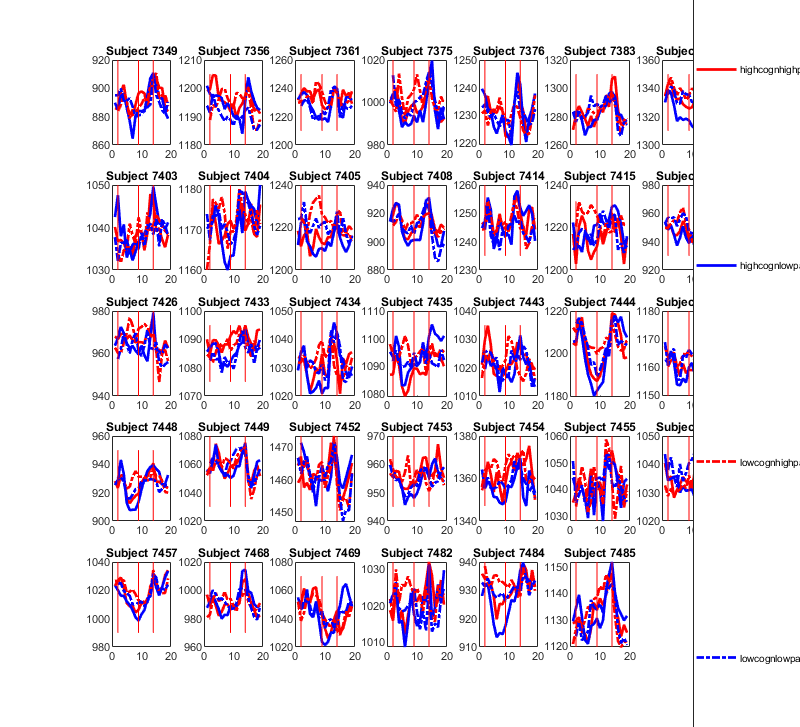

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7349\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7349The number of columns within the funcitonal mask: 769
Subject:7349The number of columns acitvating in each run(t>0) for cognition: 206
Subject:7349The number of columns acitvating in each run(t>0) for pain: 496
Subject:7349The number of columns acitvating in each run(t>0) for cognition AND pain: 143
-------------------------------------------------------------
Subject:7349The number of columns within the funcitonal mask: 769
Subject:7349The number of columns acitvating in each run(t>1) for cognition: 50
Subject:7349The number of columns acitvating in each run(t>1) for pain: 206
Subject:7349The number of columns acitvating in each run(t>1) for cognition AND pain: 19
-------------------------------------------------------------
Subject:7349The number of columns within the funcitonal mask: 1865
Subject:7349The number of columns acitvating in each run(t>0) for cognition: 658
Subject:7349The number of columns acitvating in each run(t>0) for pain: 1265
Subject:7349The number of c

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7356\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7356The number of columns within the funcitonal mask: 691
Subject:7356The number of columns acitvating in each run(t>0) for cognition: 421
Subject:7356The number of columns acitvating in each run(t>0) for pain: 314
Subject:7356The number of columns acitvating in each run(t>0) for cognition AND pain: 188
-------------------------------------------------------------
Subject:7356The number of columns within the funcitonal mask: 691
Subject:7356The number of columns acitvating in each run(t>1) for cognition: 171
Subject:7356The number of columns acitvating in each run(t>1) for pain: 108
Subject:7356The number of columns acitvating in each run(t>1) for cognition AND pain: 24
-------------------------------------------------------------
Subject:7356The number of columns within the funcitonal mask: 1383
Subject:7356The number of columns acitvating in each run(t>0) for cognition: 807
Subject:7356The number of columns acitvating in each run(t>0) for pain: 649
Subject:7356The number of c

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7361\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7361The number of columns within the funcitonal mask: 749
Subject:7361The number of columns acitvating in each run(t>0) for cognition: 378
Subject:7361The number of columns acitvating in each run(t>0) for pain: 550
Subject:7361The number of columns acitvating in each run(t>0) for cognition AND pain: 287
-------------------------------------------------------------
Subject:7361The number of columns within the funcitonal mask: 749
Subject:7361The number of columns acitvating in each run(t>1) for cognition: 128
Subject:7361The number of columns acitvating in each run(t>1) for pain: 293
Subject:7361The number of columns acitvating in each run(t>1) for cognition AND pain: 60
-------------------------------------------------------------
Subject:7361The number of columns within the funcitonal mask: 1748
Subject:7361The number of columns acitvating in each run(t>0) for cognition: 824
Subject:7361The number of columns acitvating in each run(t>0) for pain: 1413
Subject:7361The number of 

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7375\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7375The number of columns within the funcitonal mask: 699
Subject:7375The number of columns acitvating in each run(t>0) for cognition: 354
Subject:7375The number of columns acitvating in each run(t>0) for pain: 288
Subject:7375The number of columns acitvating in each run(t>0) for cognition AND pain: 171
-------------------------------------------------------------
Subject:7375The number of columns within the funcitonal mask: 699
Subject:7375The number of columns acitvating in each run(t>1) for cognition: 124
Subject:7375The number of columns acitvating in each run(t>1) for pain: 109
Subject:7375The number of columns acitvating in each run(t>1) for cognition AND pain: 26
-------------------------------------------------------------
Subject:7375The number of columns within the funcitonal mask: 1876
Subject:7375The number of columns acitvating in each run(t>0) for cognition: 841
Subject:7375The number of columns acitvating in each run(t>0) for pain: 1080
Subject:7375The number of 

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7376\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7376The number of columns within the funcitonal mask: 803
Subject:7376The number of columns acitvating in each run(t>0) for cognition: 458
Subject:7376The number of columns acitvating in each run(t>0) for pain: 510
Subject:7376The number of columns acitvating in each run(t>0) for cognition AND pain: 286
-------------------------------------------------------------
Subject:7376The number of columns within the funcitonal mask: 803
Subject:7376The number of columns acitvating in each run(t>1) for cognition: 162
Subject:7376The number of columns acitvating in each run(t>1) for pain: 219
Subject:7376The number of columns acitvating in each run(t>1) for cognition AND pain: 40
-------------------------------------------------------------
Subject:7376The number of columns within the funcitonal mask: 1683
Subject:7376The number of columns acitvating in each run(t>0) for cognition: 774
Subject:7376The number of columns acitvating in each run(t>0) for pain: 1159
Subject:7376The number of 

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7383\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7383The number of columns within the funcitonal mask: 864
Subject:7383The number of columns acitvating in each run(t>0) for cognition: 575
Subject:7383The number of columns acitvating in each run(t>0) for pain: 391
Subject:7383The number of columns acitvating in each run(t>0) for cognition AND pain: 239
-------------------------------------------------------------
Subject:7383The number of columns within the funcitonal mask: 864
Subject:7383The number of columns acitvating in each run(t>1) for cognition: 288
Subject:7383The number of columns acitvating in each run(t>1) for pain: 133
Subject:7383The number of columns acitvating in each run(t>1) for cognition AND pain: 31
-------------------------------------------------------------
Subject:7383The number of columns within the funcitonal mask: 1655
Subject:7383The number of columns acitvating in each run(t>0) for cognition: 999
Subject:7383The number of columns acitvating in each run(t>0) for pain: 677
Subject:7383The number of c

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7402\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7402The number of columns within the funcitonal mask: 1475
Subject:7402The number of columns acitvating in each run(t>0) for cognition: 1038
Subject:7402The number of columns acitvating in each run(t>0) for pain: 533
Subject:7402The number of columns acitvating in each run(t>0) for cognition AND pain: 369
-------------------------------------------------------------
Subject:7402The number of columns within the funcitonal mask: 1475
Subject:7402The number of columns acitvating in each run(t>1) for cognition: 503
Subject:7402The number of columns acitvating in each run(t>1) for pain: 130
Subject:7402The number of columns acitvating in each run(t>1) for cognition AND pain: 24
-------------------------------------------------------------
Subject:7402The number of columns within the funcitonal mask: 3258
Subject:7402The number of columns acitvating in each run(t>0) for cognition: 2582
Subject:7402The number of columns acitvating in each run(t>0) for pain: 1095
Subject:7402The number

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7403\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7403The number of columns within the funcitonal mask: 792
Subject:7403The number of columns acitvating in each run(t>0) for cognition: 455
Subject:7403The number of columns acitvating in each run(t>0) for pain: 312
Subject:7403The number of columns acitvating in each run(t>0) for cognition AND pain: 181
-------------------------------------------------------------
Subject:7403The number of columns within the funcitonal mask: 792
Subject:7403The number of columns acitvating in each run(t>1) for cognition: 161
Subject:7403The number of columns acitvating in each run(t>1) for pain: 68
Subject:7403The number of columns acitvating in each run(t>1) for cognition AND pain: 17
-------------------------------------------------------------
Subject:7403The number of columns within the funcitonal mask: 1905
Subject:7403The number of columns acitvating in each run(t>0) for cognition: 1028
Subject:7403The number of columns acitvating in each run(t>0) for pain: 816
Subject:7403The number of c

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7404\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7404The number of columns within the funcitonal mask: 749
Subject:7404The number of columns acitvating in each run(t>0) for cognition: 446
Subject:7404The number of columns acitvating in each run(t>0) for pain: 378
Subject:7404The number of columns acitvating in each run(t>0) for cognition AND pain: 221
-------------------------------------------------------------
Subject:7404The number of columns within the funcitonal mask: 749
Subject:7404The number of columns acitvating in each run(t>1) for cognition: 192
Subject:7404The number of columns acitvating in each run(t>1) for pain: 148
Subject:7404The number of columns acitvating in each run(t>1) for cognition AND pain: 34
-------------------------------------------------------------
Subject:7404The number of columns within the funcitonal mask: 1443
Subject:7404The number of columns acitvating in each run(t>0) for cognition: 883
Subject:7404The number of columns acitvating in each run(t>0) for pain: 857
Subject:7404The number of c

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7405\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7405The number of columns within the funcitonal mask: 738
Subject:7405The number of columns acitvating in each run(t>0) for cognition: 591
Subject:7405The number of columns acitvating in each run(t>0) for pain: 442
Subject:7405The number of columns acitvating in each run(t>0) for cognition AND pain: 353
-------------------------------------------------------------
Subject:7405The number of columns within the funcitonal mask: 738
Subject:7405The number of columns acitvating in each run(t>1) for cognition: 375
Subject:7405The number of columns acitvating in each run(t>1) for pain: 159
Subject:7405The number of columns acitvating in each run(t>1) for cognition AND pain: 80
-------------------------------------------------------------
Subject:7405The number of columns within the funcitonal mask: 1352
Subject:7405The number of columns acitvating in each run(t>0) for cognition: 1117
Subject:7405The number of columns acitvating in each run(t>0) for pain: 846
Subject:7405The number of 

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7408\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7408The number of columns within the funcitonal mask: 867
Subject:7408The number of columns acitvating in each run(t>0) for cognition: 537
Subject:7408The number of columns acitvating in each run(t>0) for pain: 370
Subject:7408The number of columns acitvating in each run(t>0) for cognition AND pain: 214
-------------------------------------------------------------
Subject:7408The number of columns within the funcitonal mask: 867
Subject:7408The number of columns acitvating in each run(t>1) for cognition: 218
Subject:7408The number of columns acitvating in each run(t>1) for pain: 117
Subject:7408The number of columns acitvating in each run(t>1) for cognition AND pain: 28
-------------------------------------------------------------
Subject:7408The number of columns within the funcitonal mask: 2238
Subject:7408The number of columns acitvating in each run(t>0) for cognition: 1610
Subject:7408The number of columns acitvating in each run(t>0) for pain: 869
Subject:7408The number of 

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7414\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7414The number of columns within the funcitonal mask: 738
Subject:7414The number of columns acitvating in each run(t>0) for cognition: 433
Subject:7414The number of columns acitvating in each run(t>0) for pain: 412
Subject:7414The number of columns acitvating in each run(t>0) for cognition AND pain: 237
-------------------------------------------------------------
Subject:7414The number of columns within the funcitonal mask: 738
Subject:7414The number of columns acitvating in each run(t>1) for cognition: 175
Subject:7414The number of columns acitvating in each run(t>1) for pain: 144
Subject:7414The number of columns acitvating in each run(t>1) for cognition AND pain: 35
-------------------------------------------------------------
Subject:7414The number of columns within the funcitonal mask: 1669
Subject:7414The number of columns acitvating in each run(t>0) for cognition: 977
Subject:7414The number of columns acitvating in each run(t>0) for pain: 862
Subject:7414The number of c

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7415\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7415The number of columns within the funcitonal mask: 777
Subject:7415The number of columns acitvating in each run(t>0) for cognition: 339
Subject:7415The number of columns acitvating in each run(t>0) for pain: 257
Subject:7415The number of columns acitvating in each run(t>0) for cognition AND pain: 124
-------------------------------------------------------------
Subject:7415The number of columns within the funcitonal mask: 777
Subject:7415The number of columns acitvating in each run(t>1) for cognition: 114
Subject:7415The number of columns acitvating in each run(t>1) for pain: 59
Subject:7415The number of columns acitvating in each run(t>1) for cognition AND pain: 7
-------------------------------------------------------------
Subject:7415The number of columns within the funcitonal mask: 1925
Subject:7415The number of columns acitvating in each run(t>0) for cognition: 806
Subject:7415The number of columns acitvating in each run(t>0) for pain: 726
Subject:7415The number of col

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7425\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7425The number of columns within the funcitonal mask: 615
Subject:7425The number of columns acitvating in each run(t>0) for cognition: 309
Subject:7425The number of columns acitvating in each run(t>0) for pain: 337
Subject:7425The number of columns acitvating in each run(t>0) for cognition AND pain: 195
-------------------------------------------------------------
Subject:7425The number of columns within the funcitonal mask: 615
Subject:7425The number of columns acitvating in each run(t>1) for cognition: 146
Subject:7425The number of columns acitvating in each run(t>1) for pain: 129
Subject:7425The number of columns acitvating in each run(t>1) for cognition AND pain: 49
-------------------------------------------------------------
Subject:7425The number of columns within the funcitonal mask: 1546
Subject:7425The number of columns acitvating in each run(t>0) for cognition: 714
Subject:7425The number of columns acitvating in each run(t>0) for pain: 779
Subject:7425The number of c

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7426\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7426The number of columns within the funcitonal mask: 896
Subject:7426The number of columns acitvating in each run(t>0) for cognition: 622
Subject:7426The number of columns acitvating in each run(t>0) for pain: 430
Subject:7426The number of columns acitvating in each run(t>0) for cognition AND pain: 296
-------------------------------------------------------------
Subject:7426The number of columns within the funcitonal mask: 896
Subject:7426The number of columns acitvating in each run(t>1) for cognition: 317
Subject:7426The number of columns acitvating in each run(t>1) for pain: 137
Subject:7426The number of columns acitvating in each run(t>1) for cognition AND pain: 46
-------------------------------------------------------------
Subject:7426The number of columns within the funcitonal mask: 1694
Subject:7426The number of columns acitvating in each run(t>0) for cognition: 1008
Subject:7426The number of columns acitvating in each run(t>0) for pain: 765
Subject:7426The number of 

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7433\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7433The number of columns within the funcitonal mask: 835
Subject:7433The number of columns acitvating in each run(t>0) for cognition: 385
Subject:7433The number of columns acitvating in each run(t>0) for pain: 423
Subject:7433The number of columns acitvating in each run(t>0) for cognition AND pain: 188
-------------------------------------------------------------
Subject:7433The number of columns within the funcitonal mask: 835
Subject:7433The number of columns acitvating in each run(t>1) for cognition: 127
Subject:7433The number of columns acitvating in each run(t>1) for pain: 146
Subject:7433The number of columns acitvating in each run(t>1) for cognition AND pain: 23
-------------------------------------------------------------
Subject:7433The number of columns within the funcitonal mask: 1461
Subject:7433The number of columns acitvating in each run(t>0) for cognition: 671
Subject:7433The number of columns acitvating in each run(t>0) for pain: 711
Subject:7433The number of c

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7434\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7434The number of columns within the funcitonal mask: 726
Subject:7434The number of columns acitvating in each run(t>0) for cognition: 548
Subject:7434The number of columns acitvating in each run(t>0) for pain: 432
Subject:7434The number of columns acitvating in each run(t>0) for cognition AND pain: 338
-------------------------------------------------------------
Subject:7434The number of columns within the funcitonal mask: 726
Subject:7434The number of columns acitvating in each run(t>1) for cognition: 258
Subject:7434The number of columns acitvating in each run(t>1) for pain: 162
Subject:7434The number of columns acitvating in each run(t>1) for cognition AND pain: 57
-------------------------------------------------------------
Subject:7434The number of columns within the funcitonal mask: 1488
Subject:7434The number of columns acitvating in each run(t>0) for cognition: 904
Subject:7434The number of columns acitvating in each run(t>0) for pain: 969
Subject:7434The number of c

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7435\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7435The number of columns within the funcitonal mask: 737
Subject:7435The number of columns acitvating in each run(t>0) for cognition: 495
Subject:7435The number of columns acitvating in each run(t>0) for pain: 308
Subject:7435The number of columns acitvating in each run(t>0) for cognition AND pain: 202
-------------------------------------------------------------
Subject:7435The number of columns within the funcitonal mask: 737
Subject:7435The number of columns acitvating in each run(t>1) for cognition: 249
Subject:7435The number of columns acitvating in each run(t>1) for pain: 73
Subject:7435The number of columns acitvating in each run(t>1) for cognition AND pain: 27
-------------------------------------------------------------
Subject:7435The number of columns within the funcitonal mask: 1336
Subject:7435The number of columns acitvating in each run(t>0) for cognition: 1027
Subject:7435The number of columns acitvating in each run(t>0) for pain: 552
Subject:7435The number of c

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7443\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7443The number of columns within the funcitonal mask: 897
Subject:7443The number of columns acitvating in each run(t>0) for cognition: 552
Subject:7443The number of columns acitvating in each run(t>0) for pain: 515
Subject:7443The number of columns acitvating in each run(t>0) for cognition AND pain: 316
-------------------------------------------------------------
Subject:7443The number of columns within the funcitonal mask: 897
Subject:7443The number of columns acitvating in each run(t>1) for cognition: 236
Subject:7443The number of columns acitvating in each run(t>1) for pain: 205
Subject:7443The number of columns acitvating in each run(t>1) for cognition AND pain: 53
-------------------------------------------------------------
Subject:7443The number of columns within the funcitonal mask: 1369
Subject:7443The number of columns acitvating in each run(t>0) for cognition: 695
Subject:7443The number of columns acitvating in each run(t>0) for pain: 766
Subject:7443The number of c

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7444\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7444The number of columns within the funcitonal mask: 976
Subject:7444The number of columns acitvating in each run(t>0) for cognition: 683
Subject:7444The number of columns acitvating in each run(t>0) for pain: 573
Subject:7444The number of columns acitvating in each run(t>0) for cognition AND pain: 397
-------------------------------------------------------------
Subject:7444The number of columns within the funcitonal mask: 976
Subject:7444The number of columns acitvating in each run(t>1) for cognition: 354
Subject:7444The number of columns acitvating in each run(t>1) for pain: 193
Subject:7444The number of columns acitvating in each run(t>1) for cognition AND pain: 69
-------------------------------------------------------------
Subject:7444The number of columns within the funcitonal mask: 2159
Subject:7444The number of columns acitvating in each run(t>0) for cognition: 1648
Subject:7444The number of columns acitvating in each run(t>0) for pain: 1308
Subject:7444The number of

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7445\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7445The number of columns within the funcitonal mask: 692
Subject:7445The number of columns acitvating in each run(t>0) for cognition: 365
Subject:7445The number of columns acitvating in each run(t>0) for pain: 331
Subject:7445The number of columns acitvating in each run(t>0) for cognition AND pain: 159
-------------------------------------------------------------
Subject:7445The number of columns within the funcitonal mask: 692
Subject:7445The number of columns acitvating in each run(t>1) for cognition: 152
Subject:7445The number of columns acitvating in each run(t>1) for pain: 109
Subject:7445The number of columns acitvating in each run(t>1) for cognition AND pain: 13
-------------------------------------------------------------
Subject:7445The number of columns within the funcitonal mask: 1635
Subject:7445The number of columns acitvating in each run(t>0) for cognition: 826
Subject:7445The number of columns acitvating in each run(t>0) for pain: 852
Subject:7445The number of c

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7448\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7448The number of columns within the funcitonal mask: 980
Subject:7448The number of columns acitvating in each run(t>0) for cognition: 733
Subject:7448The number of columns acitvating in each run(t>0) for pain: 595
Subject:7448The number of columns acitvating in each run(t>0) for cognition AND pain: 466
-------------------------------------------------------------
Subject:7448The number of columns within the funcitonal mask: 980
Subject:7448The number of columns acitvating in each run(t>1) for cognition: 371
Subject:7448The number of columns acitvating in each run(t>1) for pain: 260
Subject:7448The number of columns acitvating in each run(t>1) for cognition AND pain: 113
-------------------------------------------------------------
Subject:7448The number of columns within the funcitonal mask: 1698
Subject:7448The number of columns acitvating in each run(t>0) for cognition: 1259
Subject:7448The number of columns acitvating in each run(t>0) for pain: 993
Subject:7448The number of

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7449\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7449The number of columns within the funcitonal mask: 963
Subject:7449The number of columns acitvating in each run(t>0) for cognition: 508
Subject:7449The number of columns acitvating in each run(t>0) for pain: 369
Subject:7449The number of columns acitvating in each run(t>0) for cognition AND pain: 206
-------------------------------------------------------------
Subject:7449The number of columns within the funcitonal mask: 963
Subject:7449The number of columns acitvating in each run(t>1) for cognition: 191
Subject:7449The number of columns acitvating in each run(t>1) for pain: 101
Subject:7449The number of columns acitvating in each run(t>1) for cognition AND pain: 22
-------------------------------------------------------------
Subject:7449The number of columns within the funcitonal mask: 1652
Subject:7449The number of columns acitvating in each run(t>0) for cognition: 818
Subject:7449The number of columns acitvating in each run(t>0) for pain: 566
Subject:7449The number of c

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7452\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7452The number of columns within the funcitonal mask: 866
Subject:7452The number of columns acitvating in each run(t>0) for cognition: 502
Subject:7452The number of columns acitvating in each run(t>0) for pain: 398
Subject:7452The number of columns acitvating in each run(t>0) for cognition AND pain: 225
-------------------------------------------------------------
Subject:7452The number of columns within the funcitonal mask: 866
Subject:7452The number of columns acitvating in each run(t>1) for cognition: 196
Subject:7452The number of columns acitvating in each run(t>1) for pain: 114
Subject:7452The number of columns acitvating in each run(t>1) for cognition AND pain: 19
-------------------------------------------------------------
Subject:7452The number of columns within the funcitonal mask: 1462
Subject:7452The number of columns acitvating in each run(t>0) for cognition: 775
Subject:7452The number of columns acitvating in each run(t>0) for pain: 638
Subject:7452The number of c

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7453\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7453The number of columns within the funcitonal mask: 870
Subject:7453The number of columns acitvating in each run(t>0) for cognition: 416
Subject:7453The number of columns acitvating in each run(t>0) for pain: 465
Subject:7453The number of columns acitvating in each run(t>0) for cognition AND pain: 245
-------------------------------------------------------------
Subject:7453The number of columns within the funcitonal mask: 870
Subject:7453The number of columns acitvating in each run(t>1) for cognition: 148
Subject:7453The number of columns acitvating in each run(t>1) for pain: 141
Subject:7453The number of columns acitvating in each run(t>1) for cognition AND pain: 30
-------------------------------------------------------------
Subject:7453The number of columns within the funcitonal mask: 1679
Subject:7453The number of columns acitvating in each run(t>0) for cognition: 793
Subject:7453The number of columns acitvating in each run(t>0) for pain: 845
Subject:7453The number of c

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7454\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7454The number of columns within the funcitonal mask: 832
Subject:7454The number of columns acitvating in each run(t>0) for cognition: 519
Subject:7454The number of columns acitvating in each run(t>0) for pain: 420
Subject:7454The number of columns acitvating in each run(t>0) for cognition AND pain: 238
-------------------------------------------------------------
Subject:7454The number of columns within the funcitonal mask: 832
Subject:7454The number of columns acitvating in each run(t>1) for cognition: 224
Subject:7454The number of columns acitvating in each run(t>1) for pain: 146
Subject:7454The number of columns acitvating in each run(t>1) for cognition AND pain: 33
-------------------------------------------------------------
Subject:7454The number of columns within the funcitonal mask: 1689
Subject:7454The number of columns acitvating in each run(t>0) for cognition: 1078
Subject:7454The number of columns acitvating in each run(t>0) for pain: 994
Subject:7454The number of 

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7455\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7455The number of columns within the funcitonal mask: 748
Subject:7455The number of columns acitvating in each run(t>0) for cognition: 380
Subject:7455The number of columns acitvating in each run(t>0) for pain: 467
Subject:7455The number of columns acitvating in each run(t>0) for cognition AND pain: 231
-------------------------------------------------------------
Subject:7455The number of columns within the funcitonal mask: 748
Subject:7455The number of columns acitvating in each run(t>1) for cognition: 136
Subject:7455The number of columns acitvating in each run(t>1) for pain: 177
Subject:7455The number of columns acitvating in each run(t>1) for cognition AND pain: 34
-------------------------------------------------------------
Subject:7455The number of columns within the funcitonal mask: 1456
Subject:7455The number of columns acitvating in each run(t>0) for cognition: 762
Subject:7455The number of columns acitvating in each run(t>0) for pain: 843
Subject:7455The number of c

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7456\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7456The number of columns within the funcitonal mask: 791
Subject:7456The number of columns acitvating in each run(t>0) for cognition: 421
Subject:7456The number of columns acitvating in each run(t>0) for pain: 336
Subject:7456The number of columns acitvating in each run(t>0) for cognition AND pain: 173
-------------------------------------------------------------
Subject:7456The number of columns within the funcitonal mask: 791
Subject:7456The number of columns acitvating in each run(t>1) for cognition: 177
Subject:7456The number of columns acitvating in each run(t>1) for pain: 96
Subject:7456The number of columns acitvating in each run(t>1) for cognition AND pain: 21
-------------------------------------------------------------
Subject:7456The number of columns within the funcitonal mask: 1393
Subject:7456The number of columns acitvating in each run(t>0) for cognition: 753
Subject:7456The number of columns acitvating in each run(t>0) for pain: 660
Subject:7456The number of co

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7457\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7457The number of columns within the funcitonal mask: 788
Subject:7457The number of columns acitvating in each run(t>0) for cognition: 480
Subject:7457The number of columns acitvating in each run(t>0) for pain: 383
Subject:7457The number of columns acitvating in each run(t>0) for cognition AND pain: 229
-------------------------------------------------------------
Subject:7457The number of columns within the funcitonal mask: 788
Subject:7457The number of columns acitvating in each run(t>1) for cognition: 205
Subject:7457The number of columns acitvating in each run(t>1) for pain: 138
Subject:7457The number of columns acitvating in each run(t>1) for cognition AND pain: 31
-------------------------------------------------------------
Subject:7457The number of columns within the funcitonal mask: 1480
Subject:7457The number of columns acitvating in each run(t>0) for cognition: 850
Subject:7457The number of columns acitvating in each run(t>0) for pain: 866
Subject:7457The number of c

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7468\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7468The number of columns within the funcitonal mask: 706
Subject:7468The number of columns acitvating in each run(t>0) for cognition: 357
Subject:7468The number of columns acitvating in each run(t>0) for pain: 412
Subject:7468The number of columns acitvating in each run(t>0) for cognition AND pain: 212
-------------------------------------------------------------
Subject:7468The number of columns within the funcitonal mask: 706
Subject:7468The number of columns acitvating in each run(t>1) for cognition: 150
Subject:7468The number of columns acitvating in each run(t>1) for pain: 177
Subject:7468The number of columns acitvating in each run(t>1) for cognition AND pain: 47
-------------------------------------------------------------
Subject:7468The number of columns within the funcitonal mask: 1303
Subject:7468The number of columns acitvating in each run(t>0) for cognition: 622
Subject:7468The number of columns acitvating in each run(t>0) for pain: 891
Subject:7468The number of c

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7469\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7469The number of columns within the funcitonal mask: 648
Subject:7469The number of columns acitvating in each run(t>0) for cognition: 389
Subject:7469The number of columns acitvating in each run(t>0) for pain: 566
Subject:7469The number of columns acitvating in each run(t>0) for cognition AND pain: 338
-------------------------------------------------------------
Subject:7469The number of columns within the funcitonal mask: 648
Subject:7469The number of columns acitvating in each run(t>1) for cognition: 169
Subject:7469The number of columns acitvating in each run(t>1) for pain: 422
Subject:7469The number of columns acitvating in each run(t>1) for cognition AND pain: 103
-------------------------------------------------------------
Subject:7469The number of columns within the funcitonal mask: 1483
Subject:7469The number of columns acitvating in each run(t>0) for cognition: 805
Subject:7469The number of columns acitvating in each run(t>0) for pain: 1323
Subject:7469The number of

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7482\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7482The number of columns within the funcitonal mask: 870
Subject:7482The number of columns acitvating in each run(t>0) for cognition: 572
Subject:7482The number of columns acitvating in each run(t>0) for pain: 451
Subject:7482The number of columns acitvating in each run(t>0) for cognition AND pain: 279
-------------------------------------------------------------
Subject:7482The number of columns within the funcitonal mask: 870
Subject:7482The number of columns acitvating in each run(t>1) for cognition: 263
Subject:7482The number of columns acitvating in each run(t>1) for pain: 161
Subject:7482The number of columns acitvating in each run(t>1) for cognition AND pain: 34
-------------------------------------------------------------
Subject:7482The number of columns within the funcitonal mask: 1628
Subject:7482The number of columns acitvating in each run(t>0) for cognition: 1134
Subject:7482The number of columns acitvating in each run(t>0) for pain: 707
Subject:7482The number of 

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7484\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7484The number of columns within the funcitonal mask: 794
Subject:7484The number of columns acitvating in each run(t>0) for cognition: 467
Subject:7484The number of columns acitvating in each run(t>0) for pain: 420
Subject:7484The number of columns acitvating in each run(t>0) for cognition AND pain: 241
-------------------------------------------------------------
Subject:7484The number of columns within the funcitonal mask: 794
Subject:7484The number of columns acitvating in each run(t>1) for cognition: 226
Subject:7484The number of columns acitvating in each run(t>1) for pain: 148
Subject:7484The number of columns acitvating in each run(t>1) for cognition AND pain: 44
-------------------------------------------------------------
Subject:7484The number of columns within the funcitonal mask: 1473
Subject:7484The number of columns acitvating in each run(t>0) for cognition: 1086
Subject:7484The number of columns acitvating in each run(t>0) for pain: 966
Subject:7484The number of 

The loaded file path:C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\7485\functionalmasks\interimdata_rwls_S1raw.mat


Subject:7485The number of columns within the funcitonal mask: 765
Subject:7485The number of columns acitvating in each run(t>0) for cognition: 562
Subject:7485The number of columns acitvating in each run(t>0) for pain: 381
Subject:7485The number of columns acitvating in each run(t>0) for cognition AND pain: 274
-------------------------------------------------------------
Subject:7485The number of columns within the funcitonal mask: 765
Subject:7485The number of columns acitvating in each run(t>1) for cognition: 306
Subject:7485The number of columns acitvating in each run(t>1) for pain: 146
Subject:7485The number of columns acitvating in each run(t>1) for cognition AND pain: 56
-------------------------------------------------------------
Subject:7485The number of columns within the funcitonal mask: 1323
Subject:7485The number of columns acitvating in each run(t>0) for cognition: 888
Subject:7485The number of columns acitvating in each run(t>0) for pain: 714
Subject:7485The number of c

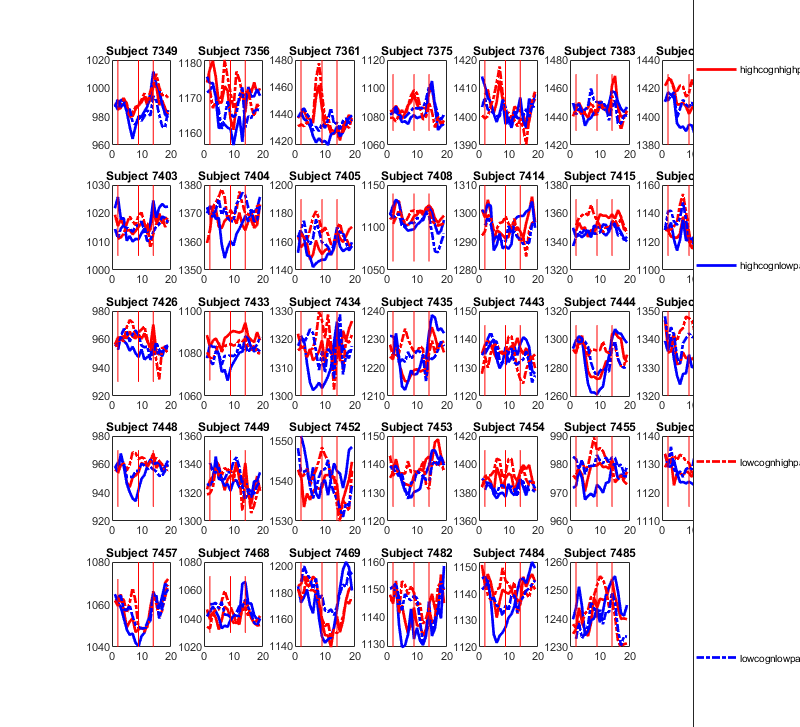

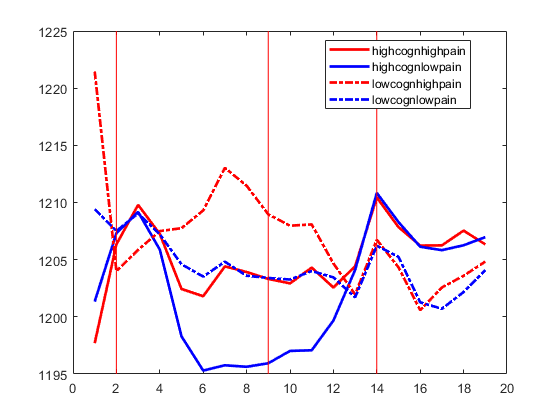

plotidx=0;
subplotsize=[8 4];
allsubjlayer={};
topcolumnnumber=200; %used this previously
layermeans = zeros(20, length(allsubj));

myroiname='S1';
hemisphere={'left' 'right'};
figuretype='raw'; %possible input: 'raw', 'tSNR', 
figurelocationpath='C:\Users\lenov\Documents\layerfMRI\E_stats\images\tomanuscipt\firstdrafts\supplementary\rawboldtrialTS\';
clustersize=200; %possible values: 200 - top 200 vertices, 0 - all vertices

for hemishperes=1:2
    figure('Position',[100, 100, 2400, 1200]);
    plotidx=0;
    for subj=allsubj
    %     roipath='C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\';
        rwdtmtrx=loadrawdatamatrix(subj,myroiname);
    %     columnartsfile=[roipath num2str(subj{:}) '\functionalmasks\interimdata_rwls_' myroiname 'raw.mat'];
    %     if exist(columnartsfile,"file")
    %         disp([num2str(subj{:}) ' subject columnar info r'])
    %         plotidx=plotidx+1;
    plotidx=plotidx+1;
    subplot(5,7,plotidx);
    if clustersize==200
            [columnwisestat,~,~]=BK_layer_sampling_pain_study_pipeline(num2cell(subj),'glmestimate',myroiname,'raw','no','maineff');
    %         allsubjid(plotidx)=subj{:};
    %         allsubjlayer{plotidx}=layerwisestat;
    %         allsubjcoldistr{plotidx}=columndistribution;
    %         allsubjstat{plotidx}=stat;
            [top200Values, top200Indices] =maxk(columnwisestat(hemishperes).T(:,3),topcolumnnumber);
            
            % Filter the indices where the values are positive
            positiveIndices = top200Indices(top200Values > 0);
            % Check if any negative values were removed
            if length(positiveIndices) < topcolumnnumber
                warning('The top 200 values contained negative numbers. Only %d positive values are retained.', length(positiveIndices));
            end
            
            tmpdata=rwdtmtrx.interimdata_columns{1,2}{hemishperes,1};
            tmpdata=tmpdata(positiveIndices,:,:);

   elseif clustersize==0
            tmpdata=rwdtmtrx.interimdata_columns{1,2}{hemishperes,1};
    end
            myspm=loadtimingfile(subj);
            trialonset=findtrialonset(myspm);
            conditionnms=fieldnames(trialonset);

            %find the values corresponding for trial onset and focus on the
            %-1 to end of trial (which can be between 19 to 22 volumes)
            vertexmean=squeeze(mean(tmpdata,1));
            roimean=mean(vertexmean,1);
            for condition=1:length(conditionnms)
                mycond=conditionnms{condition};
                myvols=trialonset.(mycond);
                condts=[];
                for trial=1:length(myvols)
                    myvol=myvols(trial);
                    if (myvol+17)<length(roimean) %this has to be put here as one subject has shorter data because of the failure of the measurement.
                        if myvol==1
                            mimi=roimean(myvol:(myvol+17));
                            mimi=[NaN,mimi];
                        else
                            mimi=roimean((myvol-1):(myvol+17));
                        end
                        condts=[condts; mimi];
                    end
                end
                trialts.(mycond)=condts;

            end
%             noise_std = std(vertexmean, 0, 2);
%             layermean=mean(vertexmean,2);
%             tSNR=layermean./noise_std;
%             if strcmp(figuretype,'raw')
%                 imagedata=layermean;
%             elseif strcmp(figuretype,'tSNR')
%                 imagedata=tSNR;
%             end
            colourcode.pain_high_cogn_high_pain='-r';
            colourcode.pain_high_cogn_low_pain='-b';
            colourcode.pain_low_cogn_high_pain='-.r';
            colourcode.pain_low_cogn_low_pain='-.b';
            legend_entries = cell(length(conditionnms), 1);
            for condition=1:length(conditionnms)
                mycond=conditionnms{condition};
                mydata=mean(trialts.(mycond));
                line_handles(condition) = plot(mydata, colourcode.(mycond), 'LineWidth', 2,'DisplayName', mycond);
                
                hold on
                legend_entries{condition} = strrep(mycond(6:end), '_', '');
                grouplvldata(plotidx).(mycond)=mydata;
            end 
            vline(2,'r');
            vline(9,'r');
            vline(14,'r');
            legend(line_handles,legend_entries, 'Location', 'bestoutside', 'Position', [0.92, 0.15, 0.05, 0.7]);
            
            title([ 'Subject ' num2str(subj)]);  % add a title to each subplot
            hold off
%             layermeans(:, plotidx) = imagedata';
    %     else
    %         disp([num2str(subj{:}) ' subject has  no sampled cluster'])
    %     end
    
    end
    saveas(gcf, [figurelocationpath myroiname hemisphere{hemishperes} 'trialts_' num2str(clustersize) 'vertices_mean_eachsubj.jpg'], 'jpeg');
    
    
    figure;  % create a new figure to visualize the layermean matrix
    legend_entries = cell(length(conditionnms), 1);
    for condition=1:length(conditionnms)
        mycond=conditionnms{condition};
        mydata=mean(vertcat(grouplvldata.(mycond)),1,"omitnan");
        line_handles(condition) = plot(mydata, colourcode.(mycond), 'LineWidth', 2,'DisplayName', mycond);
%         errorbar(mydata, std(vertcat(grouplvldata.(mycond)),[],1),  colourcode.(mycond));
        hold on
        legend_entries{condition} = strrep(mycond(6:end), '_', '');
        
    end 
    vline(2,'r');
    vline(9,'r');
    vline(14,'r');
    legend(line_handles,legend_entries, 'Location', 'best');

%     plot(1:20, mean(layermeans, 2), '-r', 'LineWidth', 1);
%     hold on
%     errorbar(1:20, mean(layermeans, 2), std(layermeans, [], 2), 'k');
%     hold off
%     xlabel('laminar depth (WM to CSF)');
%     ylabel(' raw BOLD signal');
%     title('Grand average across subjects');
    saveas(gcf, [figurelocationpath myroiname hemisphere{hemishperes} 'trialts_' num2str(clustersize) 'vertices_mean_subjavg.jpg'], 'jpeg');
end

asd

function rawdatamatrix = loadrawdatamatrix(subjid,roinm)
    % this is a wrapper to load subject level files.
    %   INPUTS:
    %       subjid: the subject ID of the participants (character array or numeric)
    %       roinm: the selected ROI name - possible options S1, S2, pIns,
    %       DLPFC
    if ~ischar(subjid)
        subjid = num2str(subjid);
    end
    filpath=['C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\' subjid '\functionalmasks\interimdata_rwls_' roinm 'raw.mat'];
    disp(['The loaded file path:' filpath])
    rawdatamatrix=load(filpath);


end

function SPMfile = loadtimingfile(subid)
    if subid <= 7405
        subpath = 'E:/pain_layers/main_project/derivatives/pipeline/';
    else
        subpath = 'D:/main_project/derivatives/pipeline/';
    end
    statspath = dir([subpath num2str(subid) '/ses-02/func/layers/rwls_stats_compcor_UNsmoothed_hpf180']);
    SPMfile = load([statspath(1).folder '/SPM.mat'],'SPM');
end

function trialvol = findtrialonset(myspm)
    conditionnms = {'pain_high_cogn_high_pain';
                    'pain_high_cogn_low_pain';
                    'pain_low_cogn_high_pain';
                    'pain_low_cogn_low_pain'};
    
    trialvol=struct();
    for condition=1:4 %the number of conditions
        condinquestion=conditionnms{condition};
%         idx=find(contains(myspm.SPM.xX.name, condinquestion));
        trialvolumestart=[];
        for run=1:3 %there is always three runs
            %this is necessary bc the first few subjects have no fixed length
            %run length, but we stopped manually.
            
            idx=strcmp(vertcat(myspm.SPM.Sess(run).U.name),condinquestion);
            trialvolumestartinrun=round(myspm.SPM.Sess(run).U(idx).ons)/3;
            if run==2
                lengthofrun1=length(myspm.SPM.Sess(1).row);
                trialvolumestartinrun=trialvolumestartinrun+lengthofrun1;
            elseif run==3
                lengthofrun12=length(myspm.SPM.Sess(1).row)+length(myspm.SPM.Sess(2).row);
                trialvolumestartinrun=trialvolumestartinrun+lengthofrun12;
            end
            
    
            trialvolumestart=[trialvolumestart; trialvolumestartinrun];
        end
        trialvol.(condinquestion)=trialvolumestart;
    end

end